# Spatial filtering

Created time : 2024/3/29 09:53

學號 : 109321019    姓名 : 涂价弘

## Exercise-1

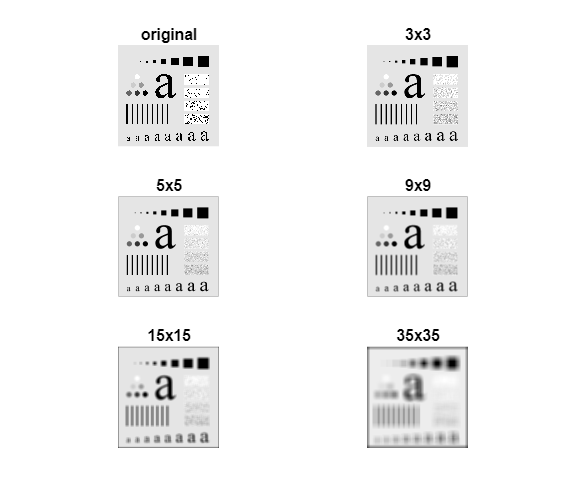

clf('reset')

img = imread('./images/3/Fig3.35(a).jpg');

subplot(3, 2, 1)
imshow(img)
title('original')

filter_sizes = [3, 5, 9, 15, 35];

for i = 1:size(filter_sizes, 2)
    filter_size = filter_sizes(i);
    f = ones(filter_size, filter_size) / filter_size * filter_size;
    filter_img = filter2(f, img, 'same');

    subplot(3, 2, i + 1)
    imshow(filter_img, [])
    title([num2str(filter_size), 'x', num2str(filter_size)])
end

## Exercise-2

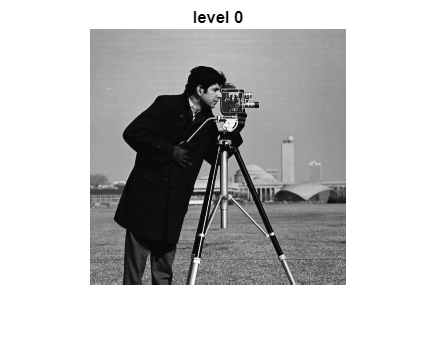

clf('reset')

img = imread('./images/2/cameraman.tif');

imshow(img)
title('level 0')

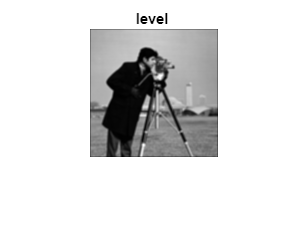

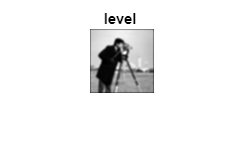

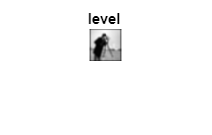


for i = 1:3
    filter = fspecial('gaussian', 5, 3);
    img = filter2(filter, img);
    img = imresize(img, 1 / 2);
    figure
    imshow(img, [])
    title('level ', num2str(i))
end

## Exercise-3

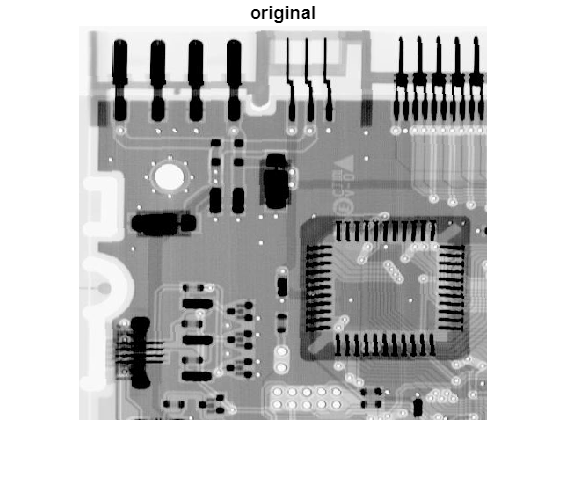

clf('reset')

img = imread('./images/ckt-board.tif');

imshow(img)
title('original')

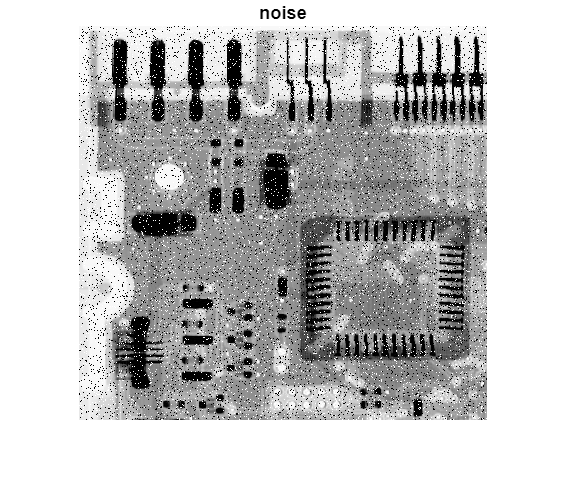


noise_img = imnoise(img, 'salt & pepper', 0.1);
imshow(noise_img)
title('noise')

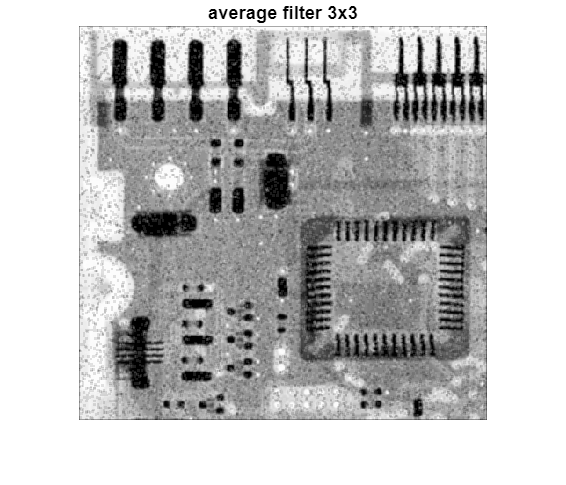


f = ones(3, 3) / 9;
average_3_img = filter2(f, noise_img);
imshow(average_3_img, [])
title('average filter 3x3')

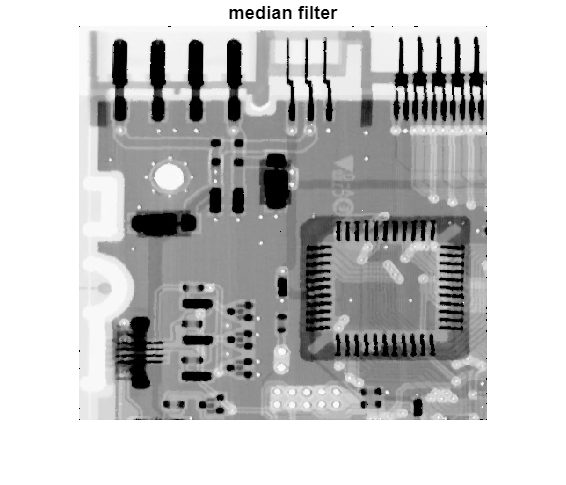


median_img = medfilt2(noise_img);
imshow(median_img, [])
title('median filter')

# Edge Detection

## Exercise-4

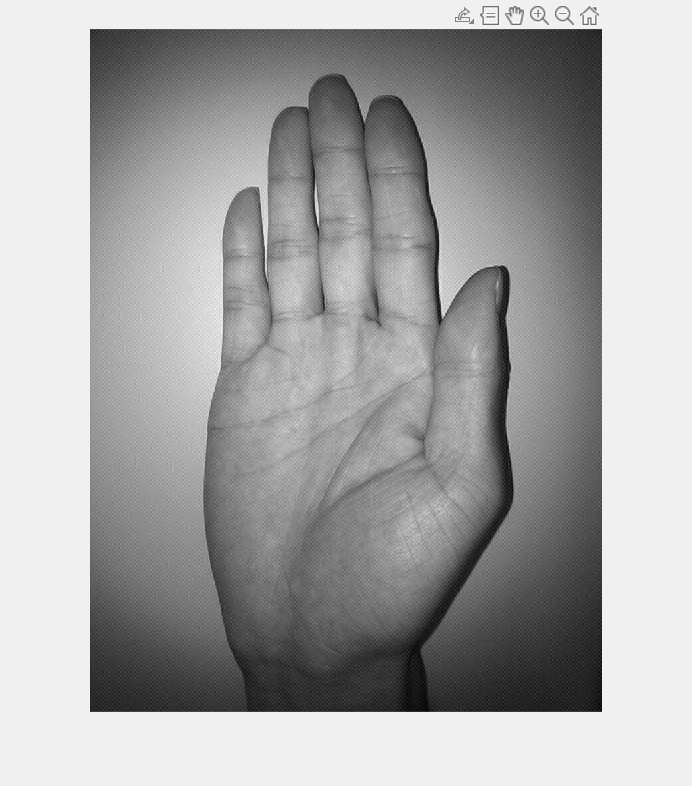

clf('reset')

img = imread('./images/palm2016.jpg');
imshow(img, [])
[x, y] = getline;

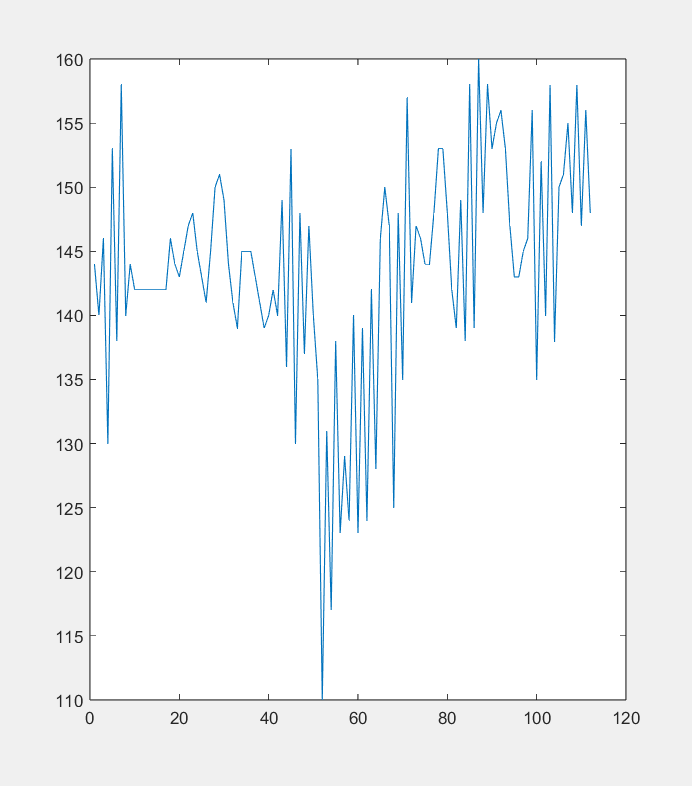

x = uint32(x);
y = uint32(y);
plot(img(y(1), x(1):x(2)))

## Exercise-5

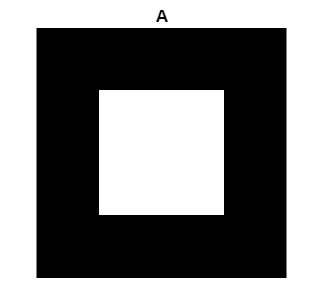

clf('reset')

A = zeros(128, 128);
A(33:96, 33:96) = 255 * ones(64, 64);

subplot(1, 3, 1)
imshow(A);
title('A')

truesize([200 200])

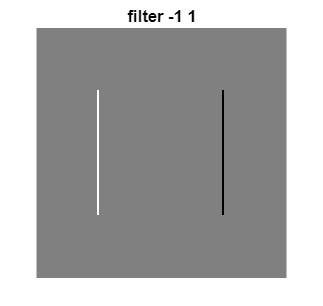


subplot(1, 3, 2)
f1 = filter2([-1, 1], A, 'same');
imshow(f1, []);
title('filter -1 1')

truesize([200 200])

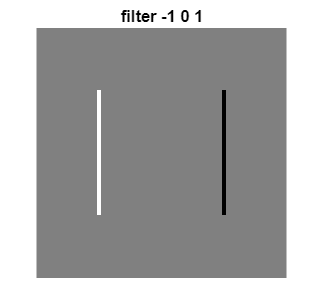


subplot(1, 3, 3)
f2 = filter2([-1, 0, 1], A, 'same');
imshow(f2, []);
title('filter -1 0 1')

truesize([200 200])

## Exercise-6

clf('reset')

A = zeros(128, 128);
A(33:96, 33:96) = 255 * ones(64, 64);
prewitt = [-1 -1 -1; 0 0 0; 1 1 1];

subplot(1, 3, 1)
imshow(A);
title('A')
truesize([200 200])

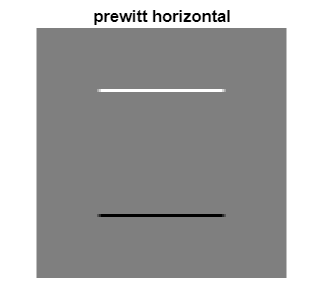


prewitt_horizontal = filter2(prewitt, A);

subplot(1, 3, 2)
imshow(prewitt_horizontal, []);
title('prewitt horizontal')
truesize([200 200])

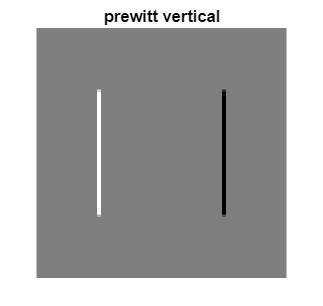


prewitt_vertical = filter2(prewitt', A);

subplot(1, 3, 3)
imshow(prewitt_vertical, []);
title('prewitt vertical')
truesize([200 200])